load("zData.mat");
figureWidth = 15; % cm (max. 15)
figureRatio = 0.4; % height to width ratio
set(groot, 'defaultTextInterpreter', 'latex')
set(groot, 'defaultAxesTickLabelInterpreter', 'latex');
set(groot, 'defaultLegendInterpreter', 'latex');
RGB = rgb2hex(orderedcolors("gem"));

g = 9.81;
I_cfRod = (1/2)*0.0211*(0.01^2 + 0.012^2); % (1/2)*m*(r1^2 + r2^2) 0.0000072;

format shortE;
CAD_I = CAD_I_gsmm*(10^-9)

CAD_I =    3.2806e-03


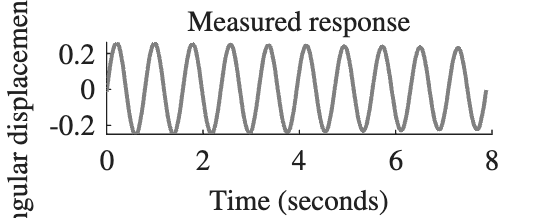

if (endIndex<0)
    y = resampledData(startIndex:end,1);
    tVec = resampledData(startIndex:end,2) - resampledData(startIndex,2);
else
    y = resampledData(startIndex:endIndex,1);
    tVec = resampledData(startIndex:endIndex,2) - resampledData(startIndex,2);
end

data = iddata(y,[],Ts,"Name","SwingTest");
data.OutputName = "\theta";
data.OutputUnit = "rad";
data.Tstart = 0;
data.TimeUnit = 's';

figure, clf, hold on
plot(tVec, y,'Color','#808080')
ylabel({'Angular displacement (rad)'},'Interpreter','latex')
xlabel('Time (seconds)','Interpreter','latex')
title('Measured response','Interpreter','latex')
set(findall(gca, 'Type', 'Line'), 'LineWidth', 1.5);
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 11);
set(gcf,'Units','centimeters','Position',[3 3 figureWidth figureRatio*figureWidth])
set(gcf,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[figureWidth figureRatio*figureWidth])
hold off

delta = (1/n)*log(magnitude_1/magnitude_n);
zeta = delta/(sqrt(4*pi()^2 + delta^2));
omega_n = (2*pi())/(tau*sqrt(1-zeta^2));

MC_I_tot = ((m*g*l*tau^2*(1-(zeta^2)))/(4*pi()^2));
format long; MC_I = MC_I_tot - m*l^2 - I_cfRod

MC_I =    0.003377207232780


format bank; MC_I_gsmm = MC_I*10^9

MC_I_gsmm =     3377207.23


MC_percDiff = 100*(MC_I-CAD_I)/CAD_I

MC_percDiff =           2.95



MC_c = 2*(MC_I_tot)*zeta*(2*pi())/(tau*sqrt(1-zeta^2));

MC_sys = idgrey('linear_greybox_ss', {m, g, l, MC_I_tot, MC_c}, 'c');

[~,MC_fit,~] = compare(MC_sys, data);
y_manual = compare(MC_sys, data).OutputData;

LSS_sys = idgrey('linear_greybox_ss', {m, g, l, I_tot_init, c_init}, 'c');
LSS_sys.Structure.Parameters(1).Free = false;
LSS_sys.Structure.Parameters(2).Free = false;
LSS_sys.Structure.Parameters(3).Free = false;
LSS_sys.Structure.Parameters(4).Minimum = 0;
LSS_sys.Structure.Parameters(5).Minimum = 0;
LSS_sys.StateName = {'\theta'; 'dtheta'};
LSS_sys.OutputName = {'\theta'};
LSS_sys.OutputUnit = 'rad';

opts = greyestOptions('InitialState','estimate', 'SearchMethod', 'lsqnonlin');
opts.SearchOptions.StepTolerance = 1e-9;
opts.SearchOptions.FunctionTolerance = 1e-9;
opts.SearchOptions.MaxIterations = 4000;
opts.SearchOptions.Advanced.MaxFunEvals = 40000;

[LSS_sys_est, x0] = greyest(data,LSS_sys,opts);

format short
LSS_WhyStop = LSS_sys_est.Report.Termination.WhyStop

LSS_WhyStop = 'Change in cost was less than the specified tolerance.'

LSS_Iterations = LSS_sys_est.Report.Termination.Iterations

LSS_Iterations = 1278

LSS_fit = LSS_sys_est.Report.Fit.FitPercent

LSS_fit = 97.8651


LSS_theta0 = x0(1);
LSS_dtheta0 = x0(2);

LSS_I_tot = LSS_sys_est.Structure.Parameters(4).Value;
format long; LSS_I = LSS_I_tot - m*l^2 - I_cfRod

LSS_I =    0.003379394084627


format bank; LSS_I_gsmm = LSS_I*10^9

LSS_I_gsmm =     3379394.08


LSS_percDiff = 100*(LSS_I-CAD_I)/CAD_I

LSS_percDiff =           3.01



format long; LSS_c = LSS_sys_est.Structure.Parameters(5).Value;

y_lin = compare(LSS_sys_est, data).OutputData;

NLSS_sys = idnlgrey('nl_greybox_ss', [1 0 2], {I_tot_init, c_init, c_bearing_init, m, g, l});
NLSS_sys.Parameters(1).Minimum = 0;            % Limit I to positive
% NLSS_sys.Parameters(1).Maximum = I_tot_init+0.1*I_tot_init; 
NLSS_sys.Parameters(2).Minimum = 0;            % Limit c to positive
NLSS_sys.Parameters(3).Fixed = true;           % Fix c_bearing
NLSS_sys.Parameters(4).Fixed = true;           % fix m
NLSS_sys.Parameters(5).Fixed = true;           % fix g
NLSS_sys.Parameters(6).Fixed = true;           % fix l
NLSS_sys.InitialStates(1).Fixed = false;       % estimate theta(0)
NLSS_sys.InitialStates(2).Fixed = false;       % estimate dtheta(0)

opts = nlgreyestOptions('SearchMethod', 'lsqnonlin');
opts.SearchOptions.StepTolerance = 1e-9;
opts.SearchOptions.FunctionTolerance = 1e-9;
opts.SearchOptions.MaxIterations = 4000;
opts.SearchOptions.Advanced.MaxFunEvals = 40000;

NLSS_sys_est = nlgreyest(data,NLSS_sys,opts);

format short
NLSS_WhyStop = NLSS_sys_est.Report.Termination.WhyStop

NLSS_WhyStop = 'Change in cost was less than the specified tolerance.'

NLSS_Iterations = NLSS_sys_est.Report.Termination.Iterations

NLSS_Iterations = 1152

NLSS_fit = NLSS_sys_est.Report.Fit.FitPercent

NLSS_fit = 97.9019



NLSS_theta0 = NLSS_sys_est.InitialStates(1).Value

NLSS_theta0 = -0.0161

NLSS_dtheta0 = NLSS_sys_est.InitialStates(2).Value

NLSS_dtheta0 = 2.0648


NLSS_I_tot = NLSS_sys_est.Parameters(1).Value;
format long; NLSS_I = NLSS_I_tot - m*l^2 - I_cfRod

NLSS_I =    0.003304230154255


format bank; NLSS_I_gsmm = NLSS_I*10^9

NLSS_I_gsmm =     3304230.15


NLSS_percDiff = 100*(NLSS_I-CAD_I)/CAD_I

NLSS_percDiff =           0.72



format long; NLSS_c = NLSS_sys_est.Parameters(2).Value;
NLSS_c_bearing = NLSS_sys_est.Parameters(3).Value/10000000;

y_nonlin = compare(NLSS_sys_est, data).OutputData;

Methods = ["CAD"; "ManualCalc"; "LSS"; "NLSS"];
I = [CAD_I; MC_I; LSS_I; NLSS_I];
percDiff = [0; MC_percDiff; LSS_percDiff; NLSS_percDiff];
fit = [0; MC_fit; LSS_fit; NLSS_fit];
c = [0; MC_c; LSS_c; NLSS_c];
theta0 = [0; MC_theta0; LSS_theta0; NLSS_theta0];
dtheta0 = [0; MC_dtheta0; LSS_dtheta0; NLSS_dtheta0];

format short;
interest = table(Methods, I, percDiff, c, theta0, dtheta0, fit);
disp(interest)

      Methods           I        percDiff        c          theta0      dtheta0     fit  
    ____________    _________    ________    __________    _________    _______    ______

    "CAD"           0.0032806          0              0            0         0          0
    "ManualCalc"    0.0033772     2.9452     0.00030758    -0.012925      2.15     97.755
    "LSS"           0.0033794     3.0119     0.00036828    -0.017427    2.0632     97.865
    "NLSS"          0.0033042    0.72073     0.00036382    -0.016102    2.0648     97.902



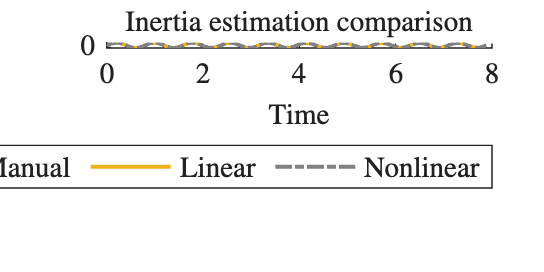


figure, clf, hold on
plot(tVec,y_manual,'Color',RGB(1))
plot(tVec,y_lin,'Color',RGB(2))
plot(tVec,y_nonlin,'Color',RGB(3))
plot(tVec,y,'Color','#808080','LineStyle','-.')
legend('Experimental','Manual', 'Linear', 'Nonlinear', 'Orientation','horizontal', 'Location','southoutside')
ylabel('Angular displacement (rad)','Interpreter','latex')
xlabel('Time','Interpreter','latex')
title('Inertia estimation comparison','Interpreter','latex')
set(findall(gca, 'Type', 'Line'), 'LineWidth', 1.5);
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 11);
set(gcf,'Units','centimeters','Position',[3 3 figureWidth (figureRatio+0.1)*figureWidth])
set(gcf,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[figureWidth figureRatio*figureWidth])
hold off